close all; 
clear all; 
clc; 
girl = imread('hw2_files\Q2\girl.jpeg')

girl = 503×386×3 uint8 数组
girl(:,:,1) =

   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   254   253   253   255   255   255   255   252   252   255   255   253   250   250   249   234   197   143    90    52    3

man = imread('hw2_files\Q2\man.jpg')

man = 512×341×3 uint8 数组
man(:,:,1) =

    96    96    97    98    99   100   101   101   103   103   104   105   106   108   108   109   111   111   112   113   114   115   116   116   117   117   118   118   119   120   121   121   124   124   124   125   126   127   127   128   128   129   129   130   131   132   132   133   134   134   135   136   137   137   138   138   139   140   140   141   141   142   143   143   144   144   145   145   146   147   147   147   147   147   148   148   149   149   150   150   151   151   151   152   152   152   153   153   154   154   155   155   156   156   157   157   156   157   157   157   158   158   158   159   160   160   160   160   161   161   161   161   161   162   162   162   163   163   163   163   165   165   165   165   165   165   165   165   166   166   166   166   166   166   166   166   166   166   166   166   166   166   166   166   166   166   166   166   166   166   166   167   168   168   168   168   168   168   168   168 

girl_features = load('hw2_files\Q2\girl_features.mat').girl_features

girl_features =   153.1250  192.6250
  243.8750  189.6250
  184.6250  264.3750
  212.8750  263.8750
  199.1250  264.3750
  159.3750  283.8750
  236.1250  285.1250
  200.1250  292.3750
  199.6250  343.6250


man_features = load('hw2_files\Q2\man_features.mat').man_features

man_features =   143.3750  176.8750
  198.0625  175.6875
  164.6875  218.5625
  176.6875  218.6875
  170.8125  215.1875
  148.8125  236.5625
  194.1875  235.5625
  172.5625  238.1875
  171.5625  277.1875


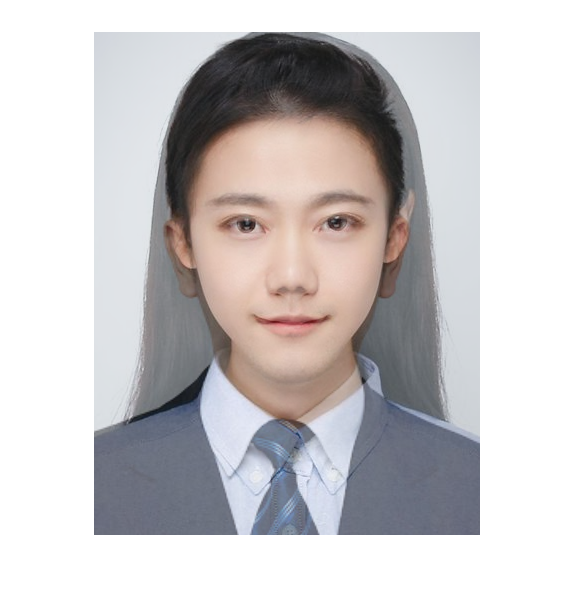


tform = fitgeotrans(man_features,girl_features,'NonreflectiveSimilarity');
man_registered = imwarp(man,tform,'OutputView',imref2d(size(girl)));
figure
imshowpair(girl,man_registered,'blend')